# State Equations

## Introduction

Eventually, the model of your quadcopter will need to include the equations that govern its flight.   These are called the Equations of State, or the State Equations.   For the quadcopter, these are written, in their simpliest form, below.

### Quadcopter State Equations

Translational motion of the body-fixed coordinate frame, where the applied forces are in the body-fixed frame and the mass of the body is assumed contant.


$$F_b =m\left(\frac{d}{\mathrm{d}t}V_b +\omega \times V_b \right)$$


The rotational dynamics of the body-fixed frame, where the applied moments are in teh body-fixed frame and the inertial tensor iis with respect to the center of gravity of the body-fixed frame.


$$M_b =I\frac{\mathrm{d}}{\mathrm{d}t}\omega +\omega \times \left(I\omega \right)$$


The relationship between the body-fixed angular velocity vector and the rate of change of the Euler angles are determined by:


$$\frac{\mathrm{d}}{\mathrm{d}t}\left\lbrack \begin{array}{c}
\phi \\
\theta \\
\psi 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & \left(\sin \phi \;\tan \theta \right) & \left(\cos \phi \;\tan \theta \right)\\
0 & \cos \phi  & -\sin \phi \\
0 & \frac{\sin \phi }{\cos \theta } & \frac{\cos \phi }{\cos \theta }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack$$


Some important variable definitions:

$\omega =\left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack$               and            $I=\left\lbrack \begin{array}{ccc}
I_{\mathrm{xx}}  & {-I}_{\mathrm{xy}}  & {-I}_{\mathrm{xz}} \\
{-I}_{\mathrm{yx}}  & I_{\mathrm{yy}}  & {-I}_{\mathrm{yz}} \\
{-I}_{\mathrm{zx}}  & {-I}_{\mathrm{zy}}  & I_{\mathrm{zz}} 
\end{array}\right\rbrack$

### A Simple Starting Point

The quadcopter state equations can all be solved numerically, but they are somewhat complicated.    As you develop the model, whether from scratch or by using another model as a starting point, it is importance that you understand what you are doing.    In this lesson the objective is to introduce you to the concept of state equations and through use of two simple examples, introduce you to the numerical processes that you will use to solve them.

In particular, the simple examples are going to be:

- A spring, mass, damper system

- A object falling under the influence of gravity subject to drag.

## Spring Mass Damper

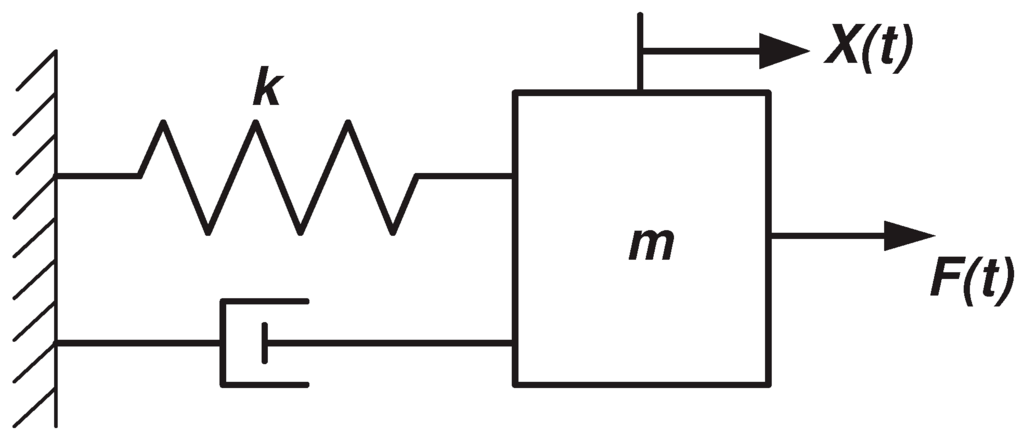

### Equation of Motion

The equation of motion of a spring-mass-damper system is a second-order ordinary differential equation.   The elements of this equation are:

- t , the independent variable of time, measured in seconds (s)

- x, the dependent variable of position, measured in meters (m)

- m, the mass, measured in kilograms (kg)

- k, the spring constant, measured in kilograms per second per second (kg/s^2)

- b, the damping constant, measured in kilograms per second (kg/s)

- F, the applied force, measured in Newtons (N)

Note that the applied force may be a constant, or a function of t and or x and or $\frac{\textrm{d}}{\textrm{d}t}x$.   


$$m\frac{{\textrm{d}}^2 }{\textrm{d}t^2 }x\left(t\right)+b\frac{\textrm{d}}{\textrm{d}t}x\left(t\right)+k\;x\left(t\right)=F\left(t,x,\frac{\textrm{d}}{\textrm{d}t}x\right)$$


The inital conditions are:

At time t=0


$$x\left(0\right)=x_0$$



$$\frac{\textrm{d}}{\textrm{d}t}x\left(0\right)=v_0$$


This is an excellent example of an equation of state. For purposes of numerical solution, it is commonly recaste into a system of first order equations.  This system is what will be referred to as the state equation for the spring-mass-damper problem.

### State Equation

The second-order ordinary differential equation can be recast as a system of first order equations, if you introduce the new variable $v\left(t\right)=\frac{\textrm{d}}{\textrm{d}t}x\left(t\right)$


$$\frac{\textrm{d}}{\textrm{d}t}\left\lbrack \begin{array}{c}
x\left(t\right)\\
v\left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{b}{m} & -\frac{k}{m}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(t\right)\\
v\left(t\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
F\left(t,x,\frac{\textrm{d}}{\textrm{d}t}x\right)
\end{array}\right\rbrack$$


with initial conditions


$$x\left(0\right)=x_0$$



$$v\left(0\right)=v_0$$


### Sample Results

m=1; b=2; k=3;     % parameters
F=@(t,x,v) 1       % applied force.  a constant in this example.

F = function_handle with value:
    @(t,x,v)1


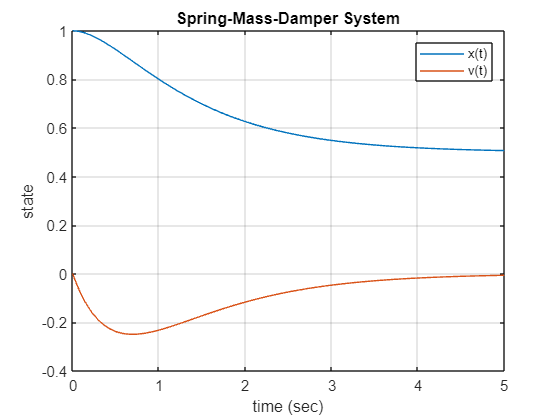


A=[0 1; -b/m -k/m];
dzdt=@(t,z)A*z+[0;F(t,z(1),z(2))];     %state equation

x0=1;  v0=0;       % initial conditions
z0=[x0;v0];

tspan=[0,5];       % time span of interest

[t,z]=ode45(dzdt,tspan,z0);

plot(t,z); xlabel('time (sec)'); ylabel('state'); legend('x(t)','v(t)');title('Spring-Mass-Damper System');grid on;

## Falling Object

### Equation of Motion


$$m\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }x\left(t\right)-{b\left(\frac{\mathrm{d}}{\mathrm{d}t}x\left(t\right)\right)}^2 =-\mathrm{mg}$$


### State Equation


$$\frac{\mathrm{d}}{\mathrm{d}t}\left\lbrack \begin{array}{c}
x\left(t\right)\\
v\left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v\left(t\right)\\
-g+\frac{b}{m}{v\left(t\right)}^2 
\end{array}\right\rbrack$$


with initial conditions


$$x\left(0\right)=x_0$$



$$v\left(0\right)=v_0$$


### Sample Results

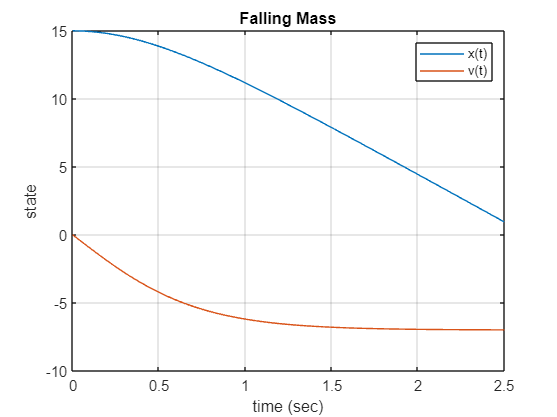

clear;
m=1; b=.2;      % parameters
g=9.81;        % gravitational acceleration

dzdt=@(t,z)[z(2);-g+b/m*z(2).^2];     %state equation

x0=15;  v0=0;       % initial conditions
z0=[x0;v0];

tspan=[0,2.5];       % time span of interest

[t,z]=ode45(dzdt,tspan,z0);

plot(t,z); xlabel('time (sec)'); ylabel('state'); legend('x(t)','v(t)');title('Falling Mass');grid on;